# CIFTI image loading and plotting

The tools below demonstrate visualization of brain maps stored in CIFTI files used by the Human Connectome Project, using Matlab-based CANlab tools, tools from the HCP Wash U group, and Jorn Diedrichsen's SUIT cerebellar toolbox. Some tools may, in the future, use Thomas Yeo's CBIG lab tools (e.g., for converting surface to MNI space).

The Matlab function **render_cifti_on_brain **renders a brain map from a CIFTI file on: 

- cortical surfaces

- medial and subcortical slices

- subcorticall surfaces

- a cerebellar flat map

This is a work in progress - please help make it better! Thank you!

### Dependencies

- CANlab Core tools

- CANlab Neuroimaging Pattern Masks repo (contains cerebellar surfaces)

- You need Wash U HCP CIFTI tools on your matlab path. 

- See https://github.com/Washington-University/HCPpipelines

- For cerebellar flatmap rendering, you need Diedrichsen's SUIT toolbox on your matlab path and SPM (for Dartel mapping to surface).

set(groot, 'DefaultFigurePosition', [200, 200, 900, 600], 'DefaultAxesFontSize', 12);

Compressed NIfTI files are not supported.
axial montage: 5531 voxels displayed, 26339 not displayed on these slices
sagittal montage: 1530 voxels displayed, 30340 not displayed on these slices


ans =   Light with properties:

       Color: [1 1 1]
       Style: 'infinite'
    Position: [1.4140 -8.6582e-17 0.0247]
     Visible: on

  Show all properties


ans =   Light with properties:

       Color: [1 1 1]
       Style: 'infinite'
    Position: [-1.2999 3.3544e-16 0]
     Visible: on

  Show all properties


Writing: 
/Users/f003vz1/Downloads/tmp_target_nii.nii
created /Users/f003vz1/Downloads/tmp_target_nii.nii

SPM12: suit_reslice_dartel (v3.0)                  13:05:47 - 12/03/2025
u_a_MNI152NLin6Asym_T1_1mm_seg1: atemp_tmp_target_nii	1,1,1
created /Users/f003vz1/Downloads/wdtmp_target_nii.nii

SPM12: suit_map2surf (v3.1)                        13:05:48 - 12/03/2025
Writing GIFTI .gii image:
created /Users/f003vz1/Downloads/tmp_target_nii.cblm_surf.gii

SPM12: suit_plotflatmap (v3.1)                     13:05:48 - 12/03/2025


### Human Connectome Project (HCP) info

**Grayordinates** in HCP CIFTI files refer to the brain locations that are represented in the combined **cortical surface vertices** and **subcortical gray-matter voxels** space�

[wiki.humanconnectome.org](https://wiki.humanconnectome.org/docs/HCP%20Users%20FAQ.html#:~:text=CIFTI%20has%20the%20advantage%20of,voxels%2C%20but%20in%20surface%20vertices)

. In HCP’s standard “91282” grayordinate space (Glasser et al. 2013), each index in a CIFTI file corresponds either to a specific vertex on the left or right fsLR 32k cortical surface, or to a specific voxel in the subcortical volumetric atlas (in MNI space). To map each grayordinate index to an actual brain location, you can use the reference surface files for cortex and the atlas label volume for subcortical structures. Below are the key resources and files that annotate these locations, along with links for download or reference:

#### Cortical Grayordinates – 32k fsLR Surface Vertices (MNI Coordinates)

HCP provides group-average **32k_fs_LR surface meshes** for each hemisphere in MNI space. These GIFTI `.surf.gii` files contain the 3D coordinate of every cortical grayordinate (vertex). For the HCP S1200 release, the relevant files are the midthickness surfaces (along with pial, white, etc.) for left and right hemisphere. For example:

- **Left hemisphere surface (32k fsLR)** – `S1200.L.midthickness_MSMAll.32k_fs_LR.surf.gii`

- **Right hemisphere surface (32k fsLR)** – `S1200.R.midthickness_MSMAll.32k_fs_LR.surf.gii`

Each of these contains ~32k vertices, of which ~29k are actual cortical grayordinates (the rest correspond to the medial wall that is typically excluded)�

[neurostars.org](https://neurostars.org/t/separate-cifti-by-structure-in-python/17301#:~:text=bml%20%3D%20,why%20is%20this%20not%2032492)

. The vertex coordinates in these files are in **MNI space**, so they directly give the XYZ location of each cortical grayordinate�

[rfmri.org](https://rfmri.org/content/how-can-i-extract-fmri-time-courses-specific-mni-coordinated-voxels-hcp-data-subjects#:~:text=see%C2%A0http%3A%2F%2Flists.humanconnectome.org%2Fpipermail%2Fhcp)

**Where to get these files:** HCP’s “S1200 Group Average Data Release” includes the group-average surfaces for both hemispheres�

[humanconnectome.org](https://www.humanconnectome.org/study/hcp-young-adult/article/s1200-group-average-data-release#:~:text=,associated%20tutorial%20for%20exploring%20the)

. You can download the full set of surfaces and maps from the ConnectomeDB S1200 release (see the *HCP_S1200_GroupAvg_v1.zip* archive)�

[humanconnectome.org](https://www.humanconnectome.org/study/hcp-young-adult/article/s1200-group-average-data-release#:~:text=Download%20the%20HCP_S1200_GroupAvg_v1,in%20ConnectomeDB)

. They are also available via the BALSA database (e.g., see *S1200.L.midthickness_MSMAll.32k_fs_LR.surf.gii* on BALSA�

[balsa.wustl.edu](https://balsa.wustl.edu/file/kNn7K#:~:text=Maps%20to%20Surface%20Maps%20to,Palette%20true%20false%20false%20false)

) and included in various HCP-compatible toolboxes and repositories (for instance, the ColeAnticevicNetPartition and **HCPpipelines** repos host these standard surfaces). Using these surface files, one can find the MNI coordinates for any cortical index (e.g., index 0 corresponds to the first vertex’s coordinates in the left surface file, etc.).

The HCP S1200 dataset provides “greyordinate” CIFTI files that include cortical surface data and cerebellar/subcortical volume data. In HCP’s 32k fs_LR space, a full **dense scalar** file with all grayordinates contains 96,854 data points – this number reflects both cortical vertices and cerebellar/subcortical voxels�

[groups.google.com](https://groups.google.com/a/humanconnectome.org/g/hcp-users/c/5Ks1sCp8v0c#:~:text=Groups%20groups.google.com%20%20CIFTI%20Dim,separate)

. For example, HCP’s *“All”* group-average maps (e.g. an **S1200 All MyelinMap** or other full brain maps) use 96,854 grayordinates, covering the entire brain including the cerebellum. By contrast, surface-only CIFTI files (cortex without subcortical regions) have 59,412 grayordinates (only cortical vertices)�

[groups.google.com](https://groups.google.com/a/humanconnectome.org/g/hcp-users/c/7WqmkMvn_LY#:~:text=Mask%20for%20CIFTI%20,I%27m)

Thus, to visualize cerebellar data on a flat map, one should use an HCP S1200 CIFTI that includes the full 96k grayordinates (ensuring the cerebellar voxels are present). The HCP S1200 “grayordinates template” or full group-average dscalar is often used for this purpose, since it contains the cerebellar data needed for flatmap projection.�

[groups.google.com](https://groups.google.com/a/humanconnectome.org/g/hcp-users/c/5Ks1sCp8v0c#:~:text=Groups%20groups.google.com%20%20CIFTI%20Dim,separate)

### render_cifti_on_brain example

#### Transcriptomic gradient 1

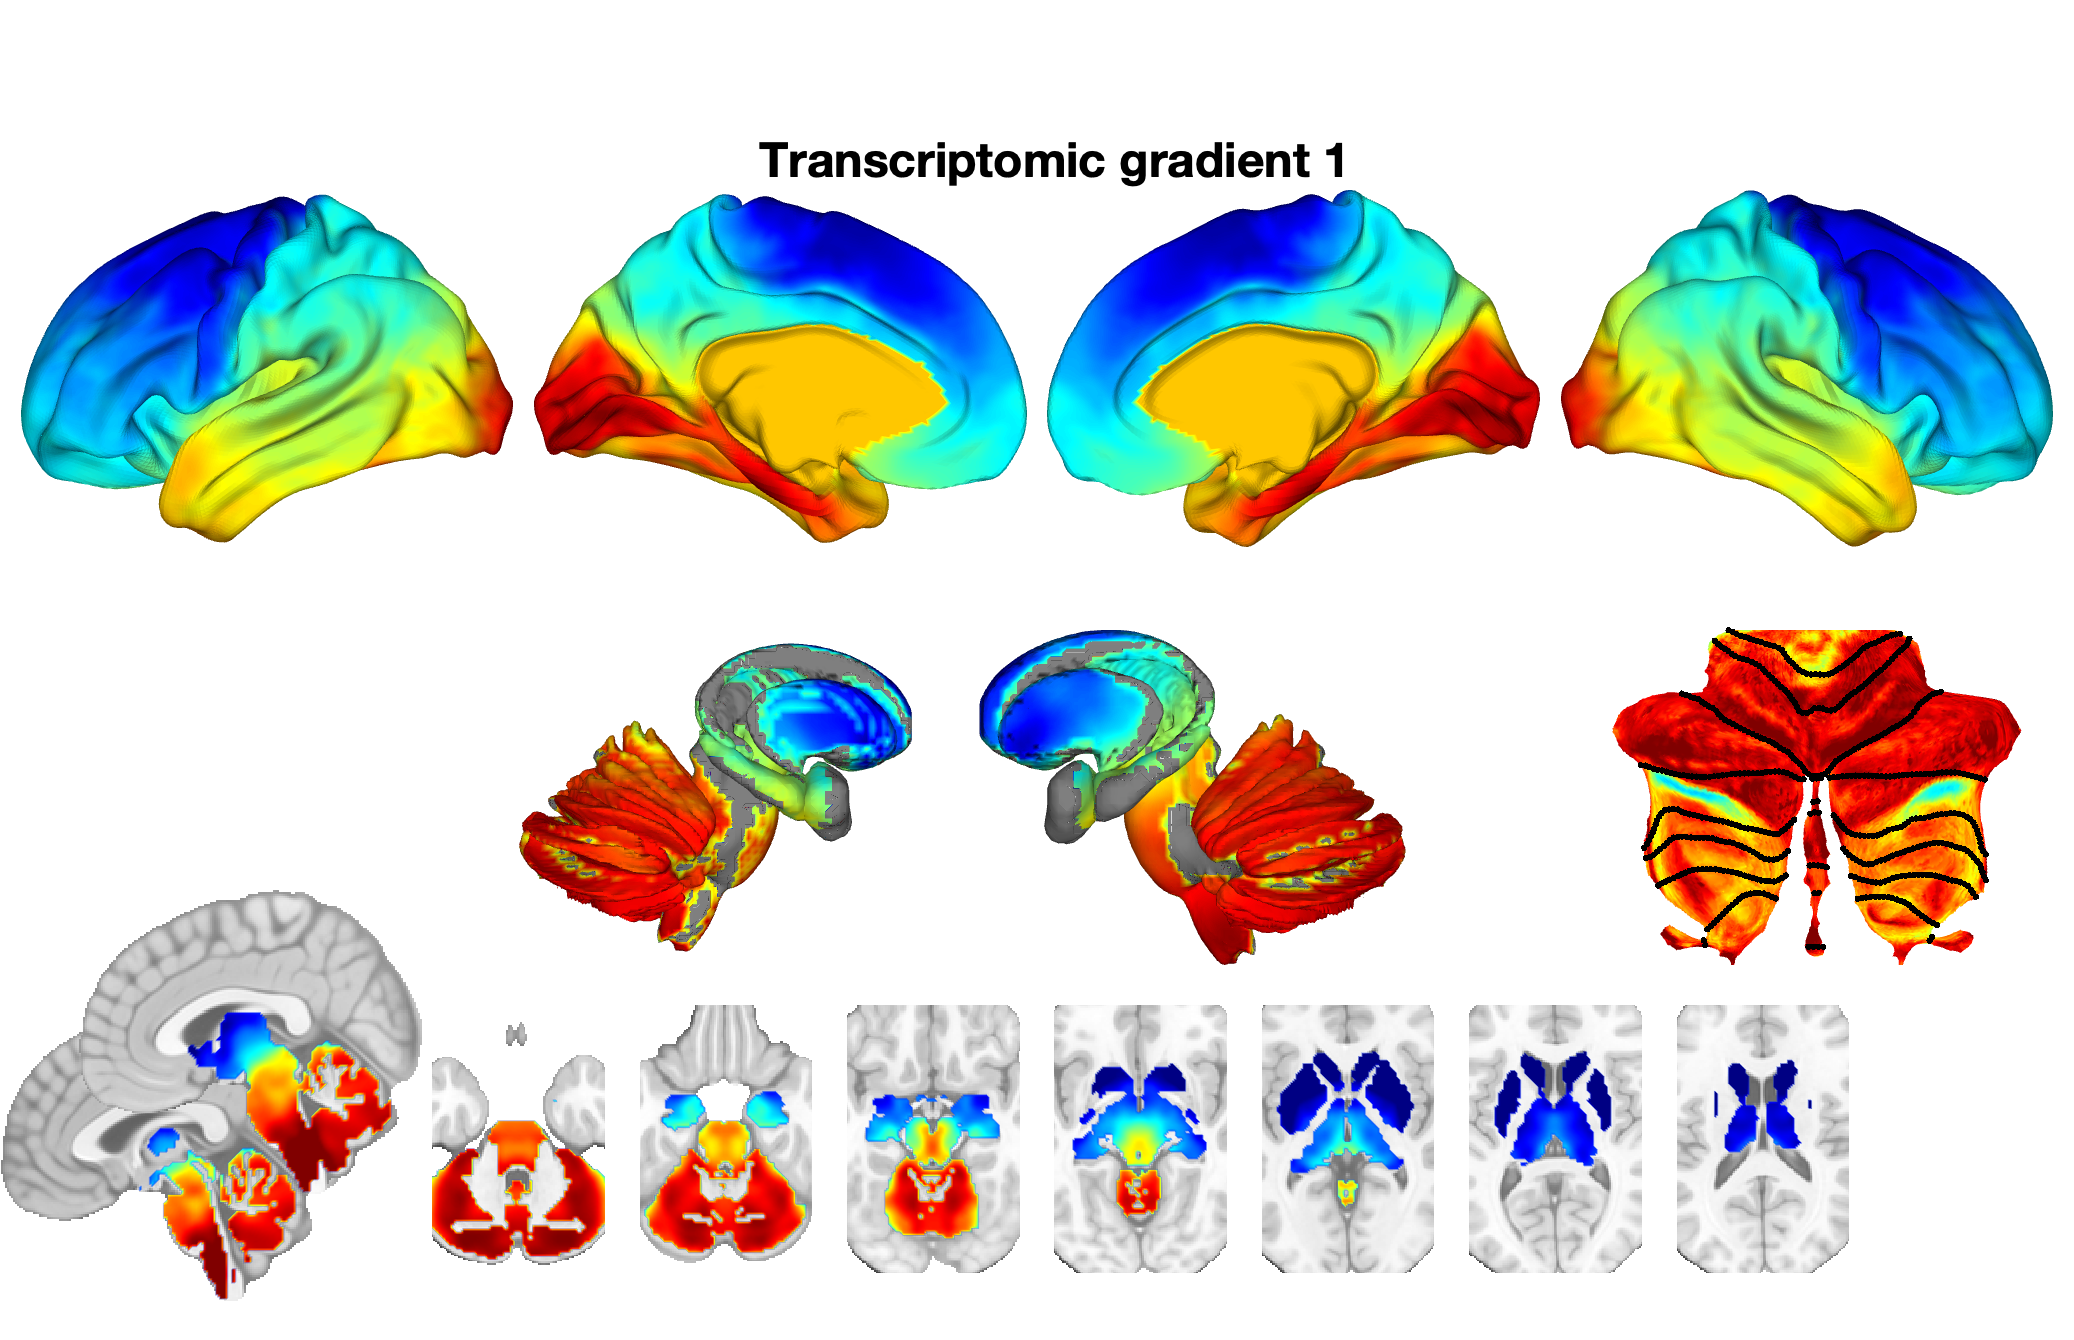

handles = render_cifti_on_brain('transcriptomic_gradients.dscalar.nii', 'which_image', 1, 'color_map', jet(256));


% Label the map
axes(handles.cortical_surface_axes(2));
title('                                         Transcriptomic gradient 1', 'Fontsize', 24)

#### Transcriptomic gradient 2

% you can pre-load a file and use that as well:
cifti_filename = 'transcriptomic_gradients.dscalar.nii'; 
cifti_read(cifti_filename);


Compressed NIfTI files are not supported.
axial montage: 5531 voxels displayed, 26339 not displayed on these slices
sagittal montage: 1530 voxels displayed, 30340 not displayed on these slices


ans =   Light with properties:

       Color: [1 1 1]
       Style: 'infinite'
    Position: [1.4140 -8.6582e-17 0.0247]
     Visible: on

  Show all properties


ans =   Light with properties:

       Color: [1 1 1]
       Style: 'infinite'
    Position: [-1.2999 3.3544e-16 0]
     Visible: on

  Show all properties


Writing: 
/Users/f003vz1/Downloads/tmp_target_nii.nii
created /Users/f003vz1/Downloads/tmp_target_nii.nii

SPM12: suit_reslice_dartel (v3.0)                  13:07:01 - 12/03/2025
u_a_MNI152NLin6Asym_T1_1mm_seg1: atemp_tmp_target_nii	1,1,1
created /Users/f003vz1/Downloads/wdtmp_target_nii.nii

SPM12: suit_map2surf (v3.1)                        13:07:01 - 12/03/2025
Writing GIFTI .gii image:
created /Users/f003vz1/Downloads/tmp_target_nii.cblm_surf.gii

SPM12: suit_plotflatmap (v3.1)                     13:07:01 - 12/03/2025


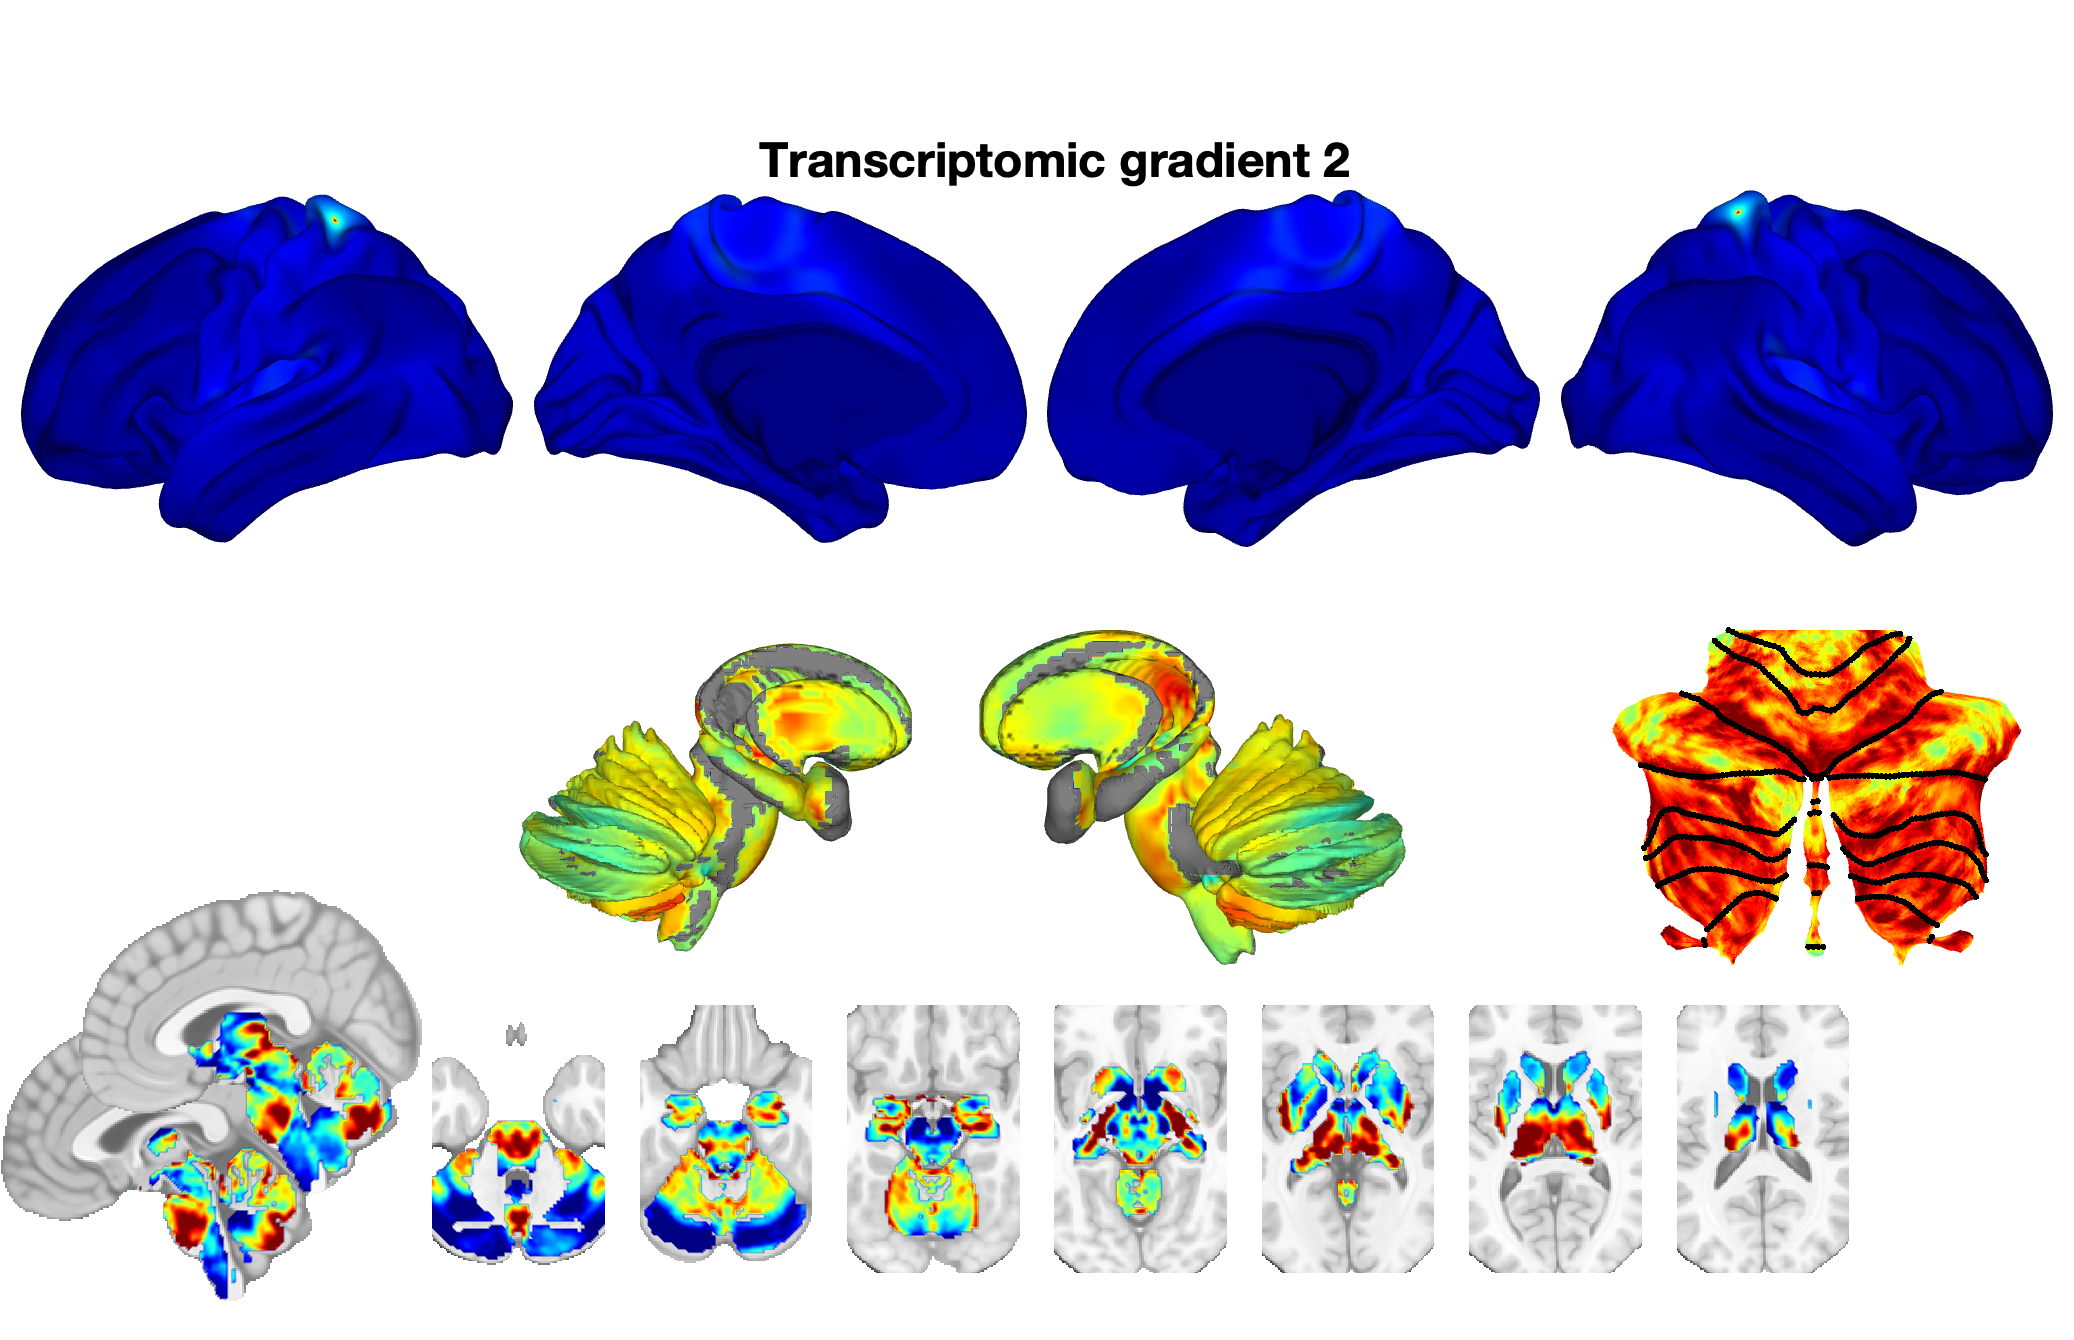

handles = render_cifti_on_brain(cifti_struct, 'which_image', 2, 'color_map', jet(256));

% Label the map
axes(handles.cortical_surface_axes(2));

title('                                         Transcriptomic gradient 2', 'Fontsize', 24)

#### Transcriptomic gradient 3

handles = render_cifti_on_brain('transcriptomic_gradients.dscalar.nii', 'which_image', 3, 'color_map', jet(256));

Compressed NIfTI files are not supported.
axial montage: 5531 voxels displayed, 26339 not displayed on these slices
sagittal montage: 1530 voxels displayed, 30340 not displayed on these slices


ans =   Light with properties:

       Color: [1 1 1]
       Style: 'infinite'
    Position: [1.4140 -8.6582e-17 0.0247]
     Visible: on

  Show all properties


ans =   Light with properties:

       Color: [1 1 1]
       Style: 'infinite'
    Position: [-1.2999 3.3544e-16 0]
     Visible: on

  Show all properties


Writing: 
/Users/f003vz1/Downloads/tmp_target_nii.nii
created /Users/f003vz1/Downloads/tmp_target_nii.nii

SPM12: suit_reslice_dartel (v3.0)                  13:10:53 - 12/03/2025
u_a_MNI152NLin6Asym_T1_1mm_seg1: atemp_tmp_target_nii	1,1,1
created /Users/f003vz1/Downloads/wdtmp_target_nii.nii

SPM12: suit_map2surf (v3.1)                        13:10:54 - 12/03/2025
Writing GIFTI .gii image:
created /Users/f003vz1/Downloads/tmp_target_nii.cblm_surf.gii

SPM12: suit_plotflatmap (v3.1)                     13:10:54 - 12/03/2025


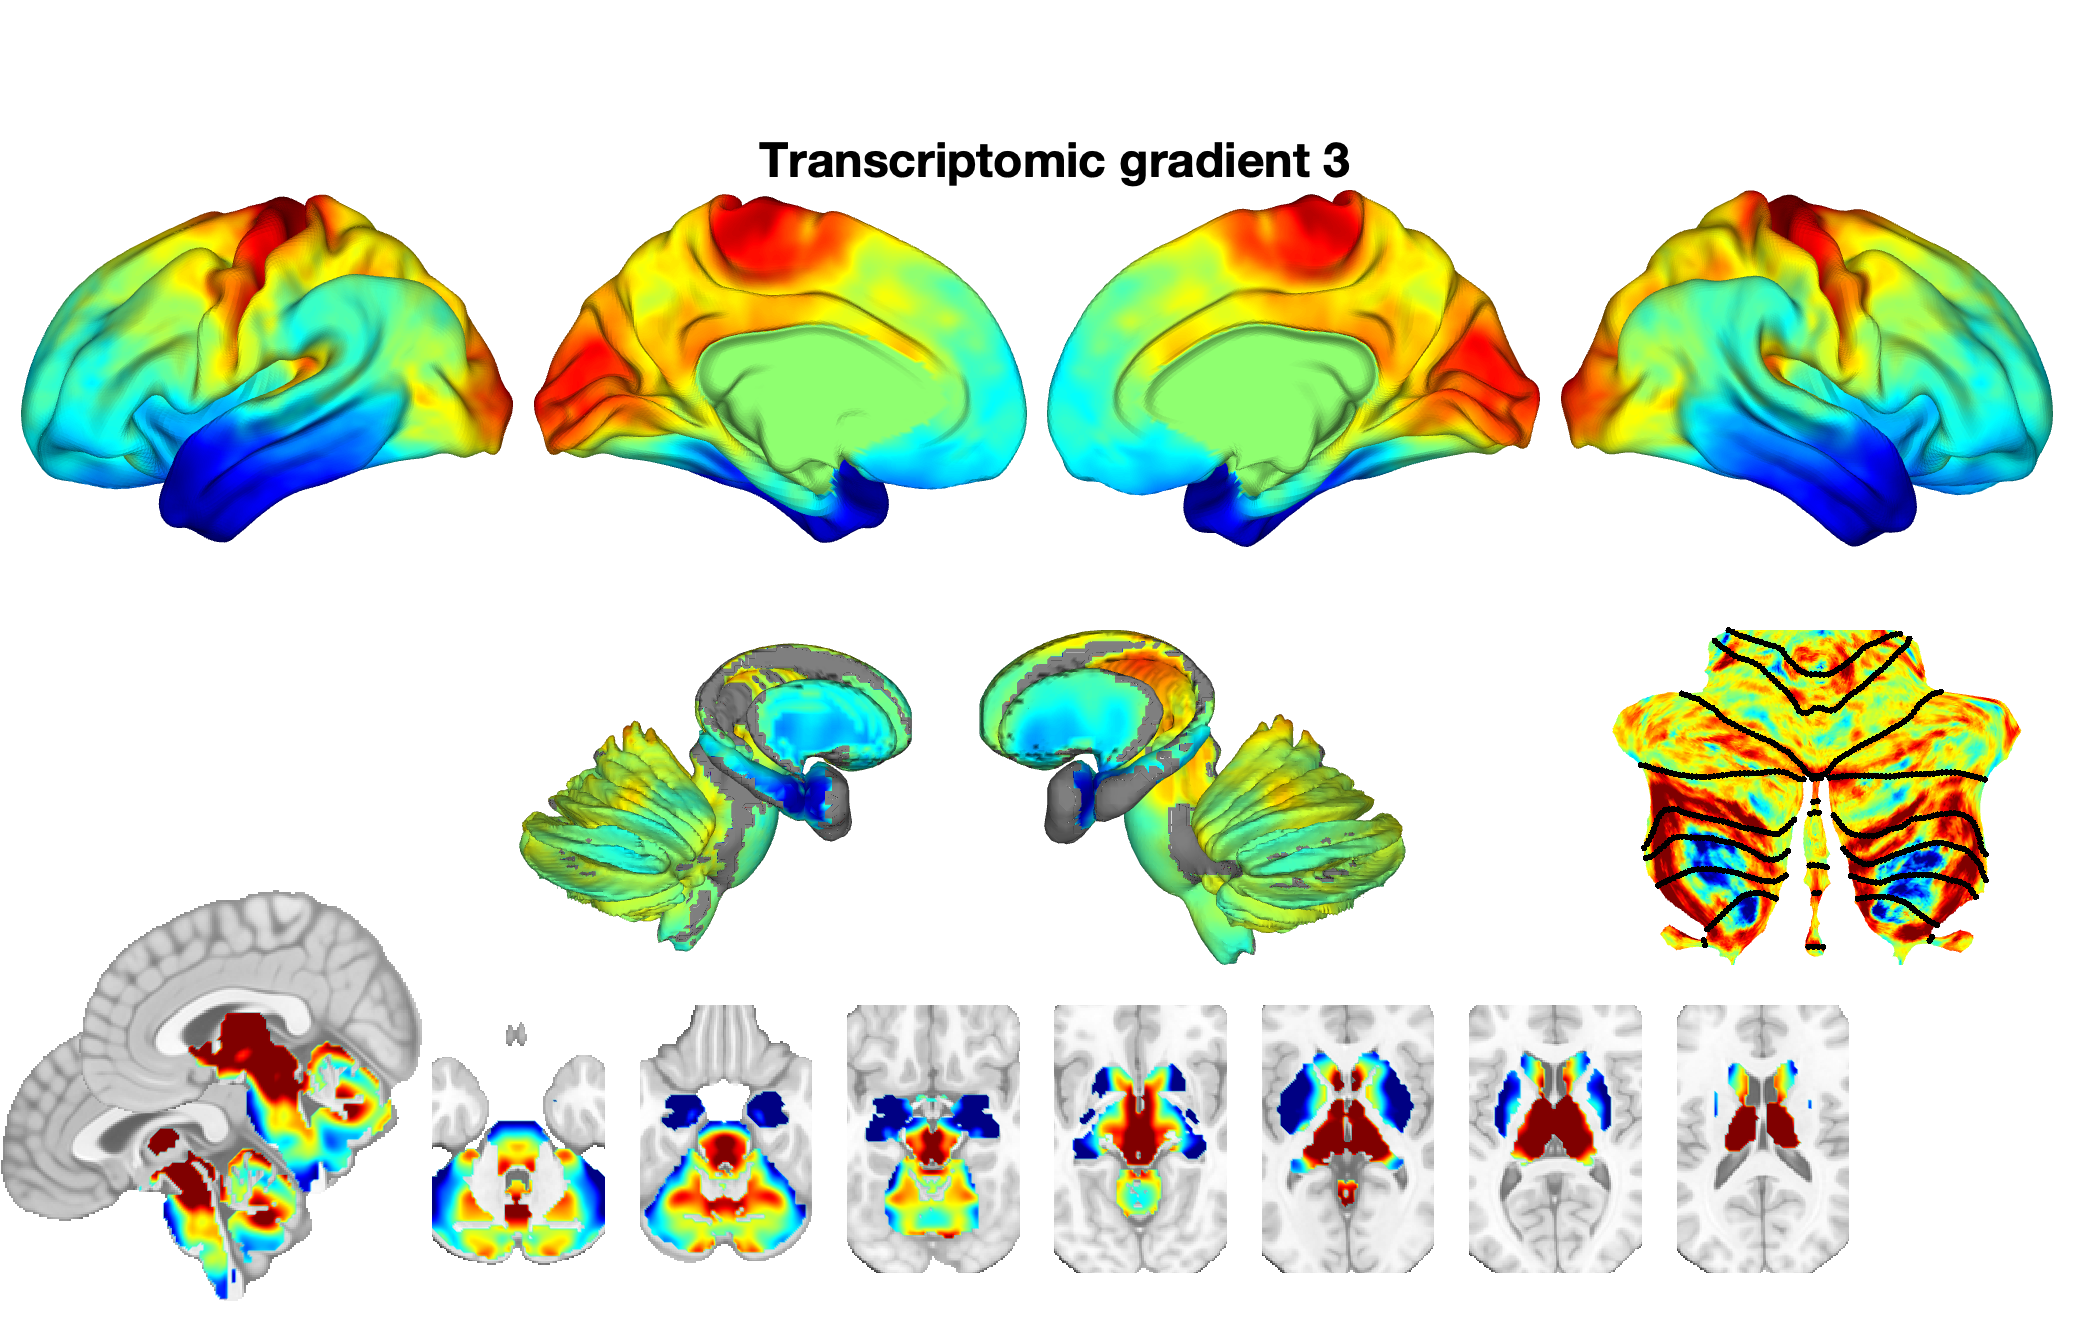


% Label the map
axes(handles.cortical_surface_axes(2));
title('                                         Transcriptomic gradient 3', 'Fontsize', 24)

### More resources

- HCP FAQ – Explanation of CIFTI grayordinates (surface vertices + subcortical voxels in MNI space)�[wiki.humanconnectome.org](https://wiki.humanconnectome.org/docs/HCP%20Users%20FAQ.html#:~:text=CIFTI%20has%20the%20advantage%20of,voxels%2C%20but%20in%20surface%20vertices).

- HCP S1200 Group Average Release – Includes downloadable 32k fsLR surface files for left/right cortex�[humanconnectome.org](https://www.humanconnectome.org/study/hcp-young-adult/article/s1200-group-average-data-release#:~:text=,associated%20tutorial%20for%20exploring%20the)�[humanconnectome.org](https://www.humanconnectome.org/study/hcp-young-adult/article/s1200-group-average-data-release#:~:text=Download%20the%20HCP_S1200_GroupAvg_v1,in%20ConnectomeDB).

- Connectome Workbench User Mailing List – Note on obtaining MNI coordinates from surface vertices via the fsLR surface files�[rfmri.org](https://rfmri.org/content/how-can-i-extract-fmri-time-courses-specific-mni-coordinated-voxels-hcp-data-subjects#:~:text=see%C2%A0http%3A%2F%2Flists.humanconnectome.org%2Fpipermail%2Fhcp).